[github: Qubit Resonance Control](https://github.com/vermakun/UMD-WS21-ECE-560-Qubit-Resonance-Control)

ECE 560 - Term Project - Kunaal Verma

Note: To run script in full, install Spinach package for MATLAB, with all pre-requisite toolboxes:

[http://spindynamics.org/wiki/index.php?title=Installation](http://spindynamics.org/wiki/index.php?title=Installation)

### Single Qubit Spin and Resonance Control

#### 1 ) Logical Model of a Qubit

The logical model of a **Qubit**  is the superposition of two basis vectors:

    
$$|\Psi \rangle =\alpha \;|0\rangle +\beta \;|1\rangle$$


where the basis vectors are,

    $\left|0\right\rangle =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$ and $\left|1\right\rangle =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$

which are the different outcomes or eigenstates of the qubit. $\alpha$ and$\beta$ are complex numbers that represent the probability that the qubit $\left|\Psi \right\rangle$ will collapse to either the $\left|0\right\rangle$ or $\left|1\right\rangle$state when measured. These probabilities are calculated as such:

    
$$\begin{array}{l}
P\left|0\right\rangle =|\alpha |^2 \\
P\left|1\right\rangle =|\beta |^2 
\end{array}$$


with the condition that the probabilities must sum to 1:

    
$$\left|\alpha {\left|\right.}^2 +|\beta |^2 =1\right.$$


It's important to note that $\left|0\right\rangle$ and $\left|1\right\rangle$ can be considered the quantum analogues of the classical bits 0 and 1, making quantum and classical computers well suited to working in hybrid systems.

This simple mathematical model of the qubit can be represented graphically using the Bloch sphere:

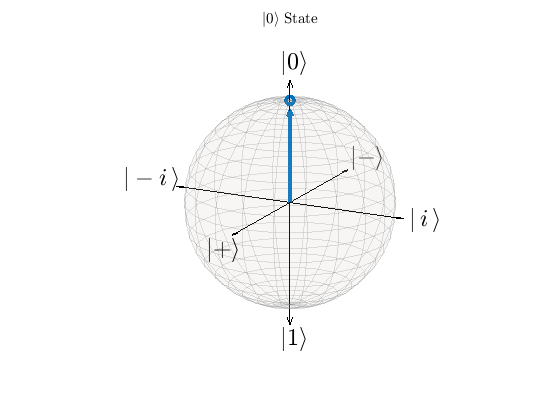

state_0 = {[1; 0]};
BlochSphere(state_0);
title('$|0\rangle$ State','interpreter','latex')

A qubit is represented by a single vector pointing to the surface of a unit sphere, which we call the Bloch sphere. When the vector is pointing up, we are indicating that the state of the qubit is in the $\left|0\right\rangle$ state, where $\alpha = 1$ and $\beta = 0$. Similarly, when the vector is pointing down, we are indicating that the state of the qubit is in the $\left|1\right\rangle$ state, where $\alpha = 0$ and $\beta = 1$.

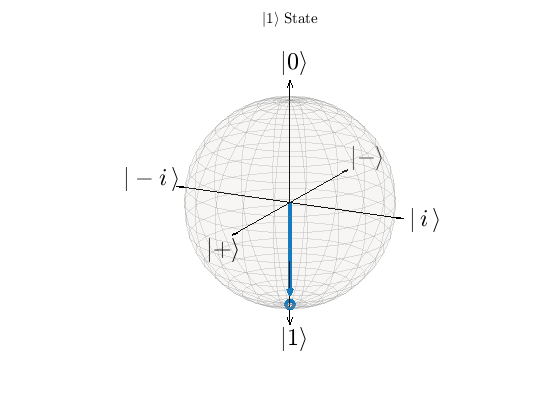

state_X = {[0; 1]};
BlochSphere(state_X);
title('$|1\rangle$ State','interpreter','latex')

Whenever this state vector points to a position on the surface that is neither the$\left|0\right\rangle$or $\left|1\right\rangle$state, the qubit is said to be in a **superposition** state.

Four of the simplest superposition states for a single qubit are the following**: **$\left|+\right\rangle$ $\left|-\right\rangle$ $\left|\;i\;\right\rangle$ $\left|-i\right\rangle$. These states lie equidistant to the states $\left|0\right\rangle$and $\left|1\right\rangle$, providing a 50/50 probability that the qubit will go to either of these eigenstates when measured.

        
$$\left|+\right\rangle =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$$


        
$$\left|-\right\rangle =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack$$


        
$$\left|\;i\;\;\right\rangle =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
i
\end{array}\right\rbrack$$


        
$$\left|-i\right\rangle =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
-i
\end{array}\right\rbrack$$


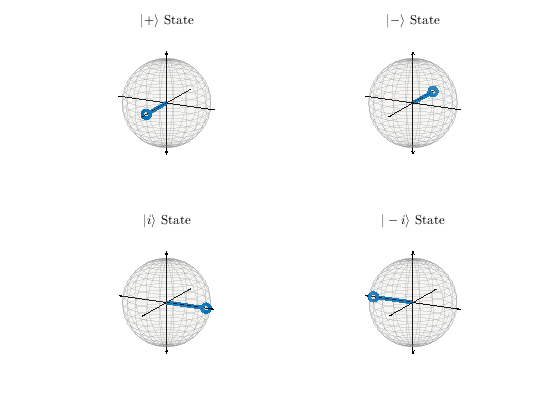

f = figure;
subplot(221);
state = {[1; 1]/sqrt(2)};
BlochSphere(state,f,1);
title('$|+\rangle$ State','interpreter','latex')

subplot(222);
state = {[1;-1]/sqrt(2)};
BlochSphere(state,f,1);
title('$|-\rangle$ State','interpreter','latex')

subplot(223);
state = {[1; 1i]/sqrt(2)};
BlochSphere(state,f,1);
title('$|i\rangle$ State','interpreter','latex')

subplot(224);
state = {[1;-1i]/sqrt(2)};
BlochSphere(state,f,1);
title('$|-i\rangle$ State','interpreter','latex')

#### 2 ) Logical Quantum Gates

The manipulation of qubits to move from one state to another requires the use of **Quantum Gates**. Quantum gates modify the vector of the qubit to rotate around the Bloch Sphere. These operations on the qubit state are entirely reversible, meaning we could return to our initial qubit state by applying the exact same operations that have already been applied in the reverse order.

To move a qubit from the $\left|0\right\rangle$state to the $\left|1\right\rangle$state, we utilize what is called the ***X*** gate, or the bit-flip gate:

    
$$X=\left\lbrack \begin{array}{cc}
0 & 1\\
1 & 0
\end{array}\right\rbrack$$


    
$$|\Psi \prime \rangle =X\;|0\rangle =\left\lbrack \begin{array}{cc}
\;0 & 1\\
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack =|1\rangle$$


This gate rotates our qubit state 180 degree about the X-axis:

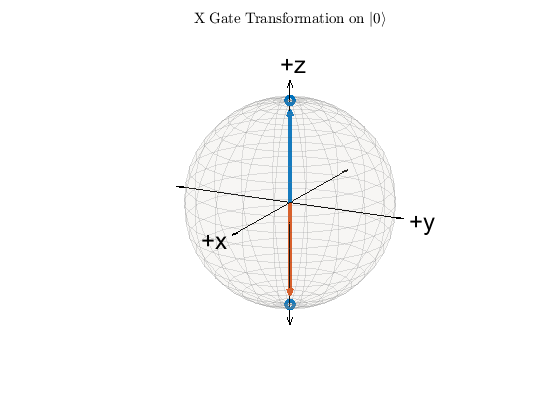

psi0 = [1; 0];
X = [0 1; 1 0];
psi1 = X*psi0;
state_X = {[psi0 psi1]};
f = figure;
BlochSphere(state_X,f,'cart');
title('X Gate Transformation on $|0\rangle$','interpreter','latex')

To move a qubit from the $\left|1\right\rangle$ to the $\left|-1\right\rangle$ state, we generally use the ***Z*** gate, or phase-flip gate:

    
$$Z=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -1
\end{array}\right\rbrack$$


    
$$|\Psi \prime \rangle =Z\;|1\rangle =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\;0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack$$


The phase-flip gate will flip the phase of $\left|1\right\rangle$, but not of $\left|0\right\rangle$:

    
$$Z\;|0\rangle =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\;1\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack =|0\rangle \;$$


It can work on our simple superposition states:

    
$$Z\;|+\rangle =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -1
\end{array}\right\rbrack \frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack =|-\rangle \;$$


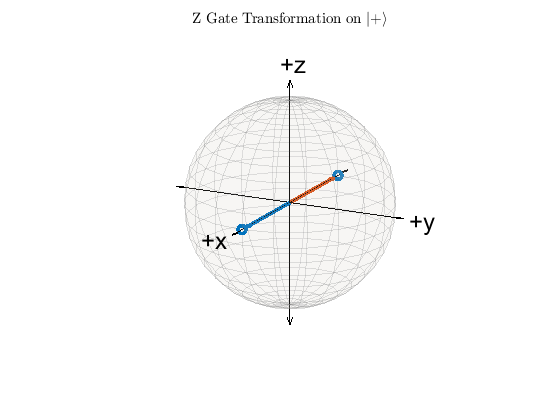

psi0 = [1; 1]/sqrt(2);
Z = [1 0; 0 -1];
psi1 = Z*psi0;
state_Z = {[psi0 psi1]};
f = figure;
BlochSphere(state_Z,f,'cart');
title('Z Gate Transformation on $|+\rangle$','interpreter','latex')

Finally, we consider how to achieve a superposition state such as $\left|+\right\rangle \;\mathrm{or}\;|-\rangle$in the first place. This can be achieved using the Hadamard gate, or ***H*** gate:

    
$$H=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack$$


The Hadamard gate has underlying rotational matrix math to describe how it operates more accurately, but effectively it rotates the state 90 degrees counterclockwise about the y-axis.

    
$$|\Psi \prime \rangle =H\;|1\rangle =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack =|-\rangle$$


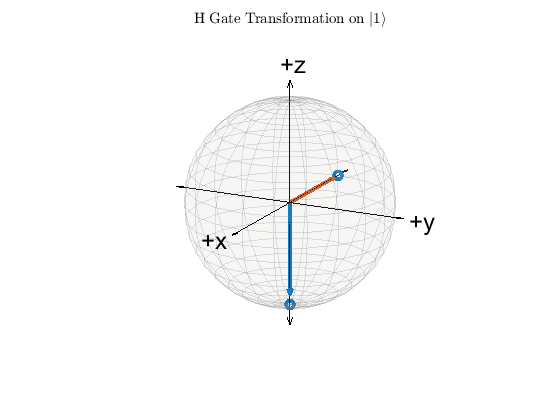

psi1 = [0; 1];
H = [1 1; 1 -1]/sqrt(2);
psip = H*psi1;
state_H = {[psi1 psip]};
f = figure;
BlochSphere(state_H,f,'cart');
title('H Gate Transformation on $|1\rangle$','interpreter','latex')

For the purposes of this document, we will limit our scope to single qubits and single qubit gates. This precludes interesting properties of quantum circuits, including quantum entangelement and interference, which require 2 or more qubit interactions.

Even so, having established the simple nature of single logical qubit states and gate operations, we will see that realizing this physically is a much more complicated effort.

#### 3 ) Spin-1/2 Model (The Phsyical Qubit)

For the purposes of analogy, we will choose the simplest physical realization of a qubit: a hydrogen atom in a vacuum. The hydrogen atom has one valence electron, and for now we will say that this electron has a symmetric probability distribution surrounding the positively charged nuclei with a certain radius. This is representative of the Bohr model for electron orbital behavior.

However, from the Stern-Gerlach experiement, we know that this model of electron orbit is innacurate. The Stern-Gerlach experiment predicts another inherent propert of atomic particles, besides mass and charge, called spin.

Spin is still a bit of a mystery, many physics textbooks define it by analogy to the classical model of a charged particle spinning around some kind of orbit. This orbital sping in turn induces a magnetic moment akin to a bar magnet. The weird thing is this "magnet" like behavior is not continuous like in a bar magnet, it is discretized or quantized.

Spin for all fermions come in multiples of $\frac{1}{2}$. The most familiar are the electron, proton, and neutron. Because spin-1/2 particles can be characterized into two eigenstates defined by spin, they are well suited to be used as qubits.

In the presence of a static magnetic field $B_0$ our Hydrogen atom in the spin up state can be mapped to the $|0\rangle$ eigenstate, and similarly in the spin down state it can be mapped to the $|1\rangle$ eigenstate. When this static magnetic field is applied, the atom can only exist in one of these two states at steady-state.

Once we are confident that the atom is in one of these two basis states, we can begin to manipulate it by applications of perpendicular magnetic pulses (either on the x or y axis), rotating the spin-frame of the atom. As seen below, a pulse rotation of $\frac{\pi }{2}$ moves the unit vector representing the atom state into the x-y plane. From our discussion on logical qubits, this is a superposition state.

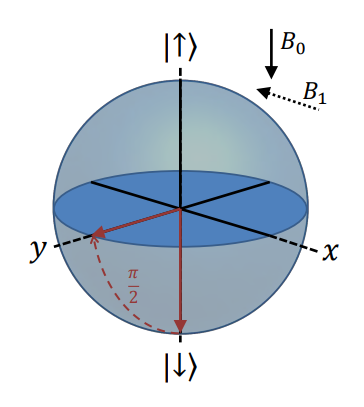

We can produce the rotational pulses by inducing magnetic pulses $B_1$ on the x-y plane. These pulses must be driven by a spin resonance frequency, $v_{res}$. In general, we can estimate $v_{res}$ using known physical quantities of the qubit system. In practice however, matching the system to $v_{res}$ requires a round of conditioning in order to match the unique $v_{res}$ of the qubit, with variations from qubit to qubit arising from yield variance. Frequency is swept across a range around the nominal $v_{res}$, and the probability of measuring spin up ($P_{\uparrow }$) is determined over $N$ samples per frequency tested. When $P_{\uparrow }$ is maximized, we have determined $v_{res}$. We shall return this topic as a possible problem to be solved using dynamic control applications.

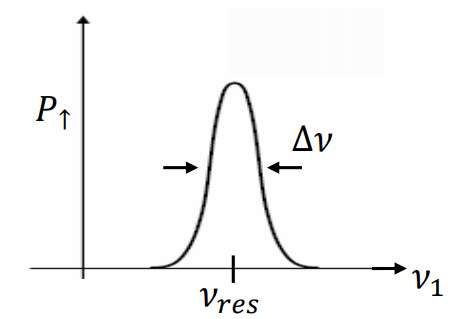

Due to environmental noise and physical imperfections of the system, this state cannot be maintained indefinitely. Eventually, the static magnetic field will decay the state of the atom back to one of the two eigenstates. This time to decay is the main peformance metric of the quality of a qubit, called the ***coherence time***. Any manipulations/rotations/processes that we desire to perform on the qubit must be made before the physical qubit decoheres and the measurement of the qubit is no longer reliable.

#### 4 ) Review of Qubit Implementations

One of the main challenges in designing a qubit system is to keep the the qubit isolated enough from other particles on the substrate or medium of the system to keep decoherence to a minimum. The following suggested technologies have varying amoutns of success in this regard, but all show promise in producing stable and scalable quantum computers in the future.

a) Superconducting

    Superconducting systems operate on similar principles that define the operation of DRAM in conventional computer hardware. DRAM essentially uses a capacitor, charged or discharged, to hold the information of a bit state, gated by a transistor. This charge is usually on the order of 100s of 1000s of electrons, where missing electrons do not effect the overall error rate of the bit.

    Superconducting qubits use a similar process, instead using supercooled metal to contain electrons in a small area, where the electrons can couple and act in unison (Cooper pairs). This is opposed to a typical thermal environment where electrons move constantly, increasing the likelihood of interactions with nearby protons and electrons. By slowing down the movement of electrons they maintain their quantum behavior, and can exist in a ground state.

    A Josephson Junction uses two of these superconductors with an insulating barrier that allows electron-pairs to pass through via quantum tunneling with a certain probability law. There are various methods of using this behavior to create a qubit (flux qubits, charge qubits, phase qubits) but ultimately it is this ability for the junction produce two readout states with a superposition probability that allows it be useful as a quantum bit.

b) Nuclear Magnetic Resonance / Electron Spin Resonance

    NMR and ESR qubit systems rely upon doping techniques to isolate an n-type atom on an island, surrounded by a pure semiconductor substrate. This atom can then be manipulated by rf elements to resonate with either the nucleus of the atom, or the electron depending on the driving frequency of the rf element.

    This type of system has the benefit of using either the nuclear qubit or electron qubit, each with their own advantages and disadvantages. Nuclear qubits can maintain a longer coherence time, on the order of a minute

c) Quantum Dot

    Quantum dot systems utilize similar techniques to modern semiconductor transistor systems, but only allowing single electrons to be passed through and held in a quantum dot well by adjusting gate voltages surrounding the well. After this is achieved, typical methods of spin resonance can be used to adjust and measure the state of the electron in a static magnetic field.

#### 4 ) Open Loop Control of Spin-1/2

    In the following script, we simulate a $^{29}Si$ substrate with an islanded $^{31}P$. We drive the pulses with a resonant frequency discovered through iterative search, and then apply rotations to implement an $H$ gate on a $|0\rangle$ state, resulting in the superposition state: $|\Psi\rangle$ = $\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$.

Target Transformation:

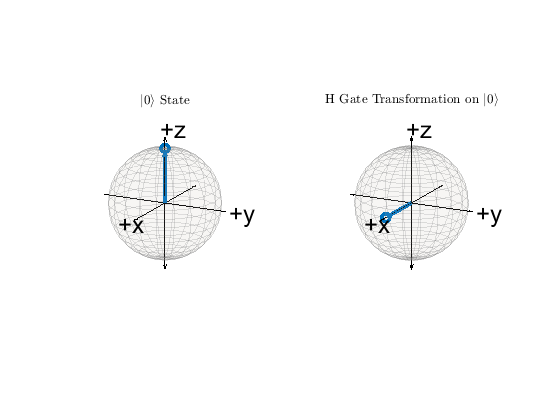

psi1 = [1; 0];
H = [1 1; 1 -1]/sqrt(2);
psip = H*psi1;
f = figure;
subplot(121)
BlochSphere({psi1},f,'cart');
title('$|0\rangle$ State','interpreter','latex')
subplot(122)
BlochSphere({psip},f,'cart');
title('H Gate Transformation on $|0\rangle$','interpreter','latex')

Simulated Transformation:

f = figure;
subplot(121)
Si_P_Hgate(50*17.2439e6,'I')

Running startup checks...


title('Initial $|0\rangle$ State','interpreter','latex')
subplot(122)
Si_P_Hgate(50*17.2439e6,'H')

Running startup checks...


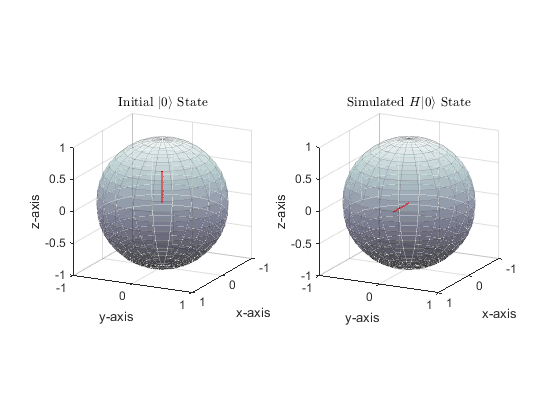

title('Simulated $H|0\rangle$ State','interpreter','latex')

#### 5 ) Proposed VCO Control for Resonance Frequency

In order to determine spin resonance frequency dynamically, a modified frequency sweep procedure can be applied to a dynamic control model in order to produce the correct spin resonance frequency on the output of the system. Because this is an iterative process, a sawtooth input is used to excite a voltage controlled oscillator to produce a frequency sweep. On the output stage, an integrator measures and sums the $|0\rangle$ and $|1\rangle$eigenstates, dividing by the sawtooth input. To check for maximization of this new signal ($P_{\uparrow }$), we use a diffentiator and provide this as negative feedback to the system. A gain must be designed to stabilize this feedback circuit.